# **Resonant frequency equation**

**2024-03-12 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

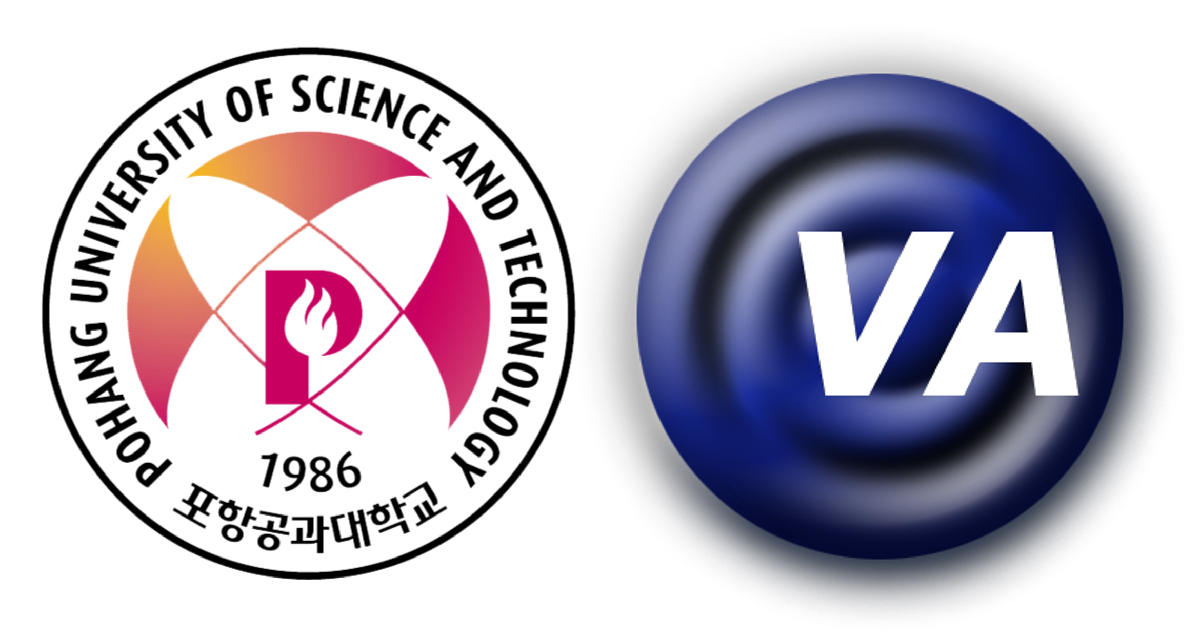

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

% clear

syms theta1 theta4

freqR = 45e3;
% freqR = 42740;
% freqR = 75990;

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');
mat.Y33D('C-21') = mat.Y33('C-21')/(1-mat.k33('C-21')^2);
mat.v3D('C-21') = sqrt(mat.Y33D('C-21')/mat.rho('C-21'));

% Lateral quarter wavelength
lambda1 = real(mat.v1('C-21')/freqR);
lambda1/4

ans = 0.0181

r1 = 10e-3;
r2 = 10e-3;
r3 = 10e-3;
r4 = 0.75e-3;
% r1 = 7e-3;
% r2 = 7e-3;
% r3 = 7e-3;
% % r4 = 0.5e-3;
% r4 = [0.5e-3 0.75e-3];
% r4 = [0.5e-3:0.05e-3:1e-3 1.1e-3:0.1e-3:2e-3 2.25e-3:0.25e-3:5e-3];

% Z1 = @(r1) mat("Aluminum",:).rho *real(mat("Aluminum",:).v3)    *pi*r1.^2;
Z1 = @(r1) mat("Stainless Steel",:).rho *real(mat("Stainless Steel",:).v3)    *pi*r1.^2;
Z2 = @(r2) mat("C-21",:).rho            *real(mat("C-21",:).v3           )    *pi*r2.^2;
Z3 = @(r3) mat("Aluminum",:).rho        *real(mat("Aluminum",:).v3       )    *pi*r3.^2;
Z4 = @(r4) mat("Aluminum",:).rho        *real(mat("Aluminum",:).v3       )    *pi*r4.^2;

% c1 = real(mat("Aluminum",:).v3);
c1 = real(mat("Stainless Steel",:).v3);
c2 = real(mat("C-21",:).v3);
c3 = real(mat("Aluminum",:).v3);
c4 = real(mat("Aluminum",:).v3);

theta = @(l,c) 2*pi*freqR/c*l;

l21 = 8e-3; % node position is at the center of piezoelectric material
pCount = 4;
% l21 = linspace(1e-3,3e-3,3);
l22 = l21;
% l3 = 2e-3;
l3 = linspace(5e-3,30e-3,26);

r4Count = length(r4);
l21Count = length(l21);
l3Count = length(l3);

[L21,L3] = meshgrid(l21,l3);
L21 = reshape(L21,[],1);
L22 = L21;
L3 = reshape(L3,[],1);
L0 = zeros(length(L21),1);

param = permute(repmat([L0 L21 L22 L3 L0 L0 L0],[1 1 r4Count]),[3 1 2]);
clear L1 L21 L22 L3 L4

l1 = zeros(length(l21),length(l3));
l4 = zeros(length(l21),length(l3));

for i = 1:r4Count
    for j = 1:l21Count
        tic
        for k = 1:l3Count
            % LHS of node
            % eqn1 = Z1(r1)/Z2(r2)*tan(theta(l21(j),c2))*tan(theta1) == 1;
            % 
            % theta1_ = double(vpasolve(eqn1,theta1,[0 pi/2]));
            % if(isempty(theta1_))
            %     param(i,(j-1)*l3Count+k,1) = c1/(4*freqR);
            % else
            %     param(i,(j-1)*l3Count+k,1) = theta1_*c1/(2*pi*freqR);
            % end
            theta1_ = atan(Z2(r2)/Z1(r1)/tan(theta(l21(j),c2)));
            if theta1_ > 0
                param(i,(j-1)*l3Count+k,1) = theta1_*c1/(2*pi*freqR);
            else
                param(i,(j-1)*l3Count+k,1) = 0;
            end

            % RHS of node
            % eqn2 = Z3(r3)/Z2(r2)*tan(theta(l22(j),c2))*tan(theta(l3(k),c3))...
            %     + Z4(r4(i))/Z3(r3)*tan(theta(l3(k),c3))*tan(theta4)...
            %     + Z4(r4(i))/Z2(r2)*tan(theta4)*tan(theta(l22(j),c2)) == 1;
            % 
            % theta4_ = double(vpasolve(eqn2,theta4,[0 pi/2]));
            % if(isempty(theta4_))
            %     param(i,(j-1)*l3Count+k,5) = 0;
            % else
            %     param(i,(j-1)*l3Count+k,5) = theta4_*c4/(2*pi*freqR);
            % end
            theta4_ = atan((1-Z3(r3)/Z2(r2)*tan(theta(l22(j),c2))*tan(theta(l3(k),c3)))/(Z4(r4(i))*(1/Z3(r3)*tan(theta(l3(k),c3))+1/Z2(r2)*tan(theta(l22(j),c2)))));
            if theta4_ > 0
                param(i,(j-1)*l3Count+k,5) = theta4_*c4/(2*pi*freqR);
            else
                param(i,(j-1)*l3Count+k,5) = 0;
            end
        end
        toc
    end
    % LHS validation
    eqn1Chk = @(l1, l2)...
        Z1(r1)/Z2(r2).*tan(theta(l2,c2)).*tan(theta(l1,c1));
    param(i,:,6) = eqn1Chk(param(i,:,1),param(i,:,2));
    paramChkidx1 = find(param(i,:,6)<=0.9999 | param(i,:,6)>=1.0001);
    param(i,paramChkidx1,:) = permute(repmat([0 0 0 0 0 0 0],[1 1 length(paramChkidx1)]),[1 3 2]);

    % RHS valiadation
    eqn2Chk = @(l2, l3, l4)...
        Z3(r3)/Z2(r2).*tan(theta(l2,c2)).*tan(theta(l3,c3)) + ...
        Z4(r4(i))/Z3(r3).*tan(theta(l3,c3)).*tan(theta(l4,c4)) + ...
        Z4(r4(i))/Z2(r2).*tan(theta(l4,c4)).*tan(theta(l2,c2));
    param(i,:,7) = eqn2Chk(param(i,:,3),param(i,:,4),param(i,:,5));
    paramChkidx2 = find(param(i,:,7)<=0.9999 | param(i,:,7)>=1.0001);
    param(i,paramChkidx2,:) = permute(repmat([0 0 0 0 0 0 0],[1 1 length(paramChkidx2)]),[1 3 2]);
end

Elapsed time is 0.090807 seconds.


f = Study.freqSolid;
% f = 50e3:10:100e3;
fCount = length(f);
uPlateGlobal = zeros(r4Count, l21Count, l3Count, fCount, 5);

% theta_ = @(l,c,f) 2*pi*f/c*l;

% Load the plate's impedance
Z_p_wo_steps= Plate.zPlateFEM;
Z_p_w_steps = Plate.zSteppedPlateFEM;

% [~,Z_p_wo_steps] = import_impedance('D -230804 - 48 kHz w.o. Steps.txt');
% [~,Z_p_w_steps] = import_impedance('D -230804 - 48 kHz w. Steps.txt');
% [~,Z_p_wo_steps] = import_impedance('D -230725 - Stepped-plate impedance w.o. steps.txt');
% [~,Z_p_w_steps] = import_impedance('D -230725 - Stepped-plate impedance w. steps.txt');

e_  = [1; 2; 3; 4];
l   = [0; 0; 0; 0];
r   = [0; 0; 0; 0];
A   = [0; 0; 0; 0];
% Mat = ["Aluminum"; "C-21"; "Aluminum"; "Aluminum"];
Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
piezoCount  = [1; pCount; 1; 1];

paramECM = table(e_, l, r, A, Mat, piezoCount);
clear e_ l r A Mat piezoCount

for i = 1:r4Count
    for j = 1:l21Count
        for k = 1:l3Count
            % tic
            % Define the parameters for ECM
            e_  = [1; 2; 3; 4];
            l   = [0; 0; 0; 0];
            r   = [0; 0; 0; 0];
            A   = [0; 0; 0; 0];
            % Mat = ["Aluminum"; "C-21"; "Aluminum"; "Aluminum"];
            Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
            piezoCount  = [1; pCount; 1; 1];
            
            paramECM = table(e_, l, r, A, Mat, piezoCount);
            clear e_ l r A Mat piezoCount

            nStart  = 1;
            nEnd    = 5;
            nCount  = nEnd - nStart+1;
            eCount  = nCount - 1;
            ePiezo  = 2;
    
            paramECM.r(1) = r1;
            paramECM.r(2) = r2;
            paramECM.r(3) = r3;
            paramECM.r(4) = r4(i);
    
            paramECM.A = pi*(paramECM.r).^2;
    
            paramECM.l(1) = squeeze(param(i,(j-1)*l3Count+k,1));
            paramECM.l(2) = squeeze(param(i,(j-1)*l3Count+k,2)) + squeeze(param(i,(j-1)*l3Count+k,3));
            paramECM.l(3) = squeeze(param(i,(j-1)*l3Count+k,4));
            paramECM.l(4) = squeeze(param(i,(j-1)*l3Count+k,5));

            if paramECM.l(1) == 0
                continue
            end
    
            % Initialize the symbols for material properties and design parameters of elements
            paramECM = sortrows(innerjoin(paramECM, mat));
    
            % Calculating the bar's impedance for symmetric T-network
            Z_b = zeros(fCount, nCount);  % Z_b
            Z_c = zeros(fCount, nCount);  % Z_c = Z_a + Z_b
            Z_d = zeros(fCount, nCount);  % Z_d for the boundary conditions of both ends
    
            for l = 1:eCount
                Z_b(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l))*paramECM.A(l)./(sin(2*pi*f./(paramECM.v3(l)).*paramECM.l(l)));
                Z_c(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l))*paramECM.A(l).*cot(2*pi*f./(paramECM.v3(l)).*paramECM.l(l));
                % Z_b(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l)./(sin(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l)));
                % Z_c(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l).*cot(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l));
            end
    
            % Initialize the symbols for effort and flow variable vectors
            F   = zeros(fCount, nCount);
            u   = zeros(fCount, nCount);
            V   = 40;
    
            % Define the bounrady conditions of both ends
            Z_d(:,1) = 0;
            Z_d(:,nCount) = Z_p_w_steps;
    
            % Constructing the impedance matrix
            Z = zeros(fCount,nCount,nCount);
            
            Z(:,1,1)        = Z_c(:,1) + Z_d(:,1);
            Z(:,1,2)        = -Z_b(:,1);
            Z(:,1,3:nCount) = 0;
    
            for l=2:nCount-1
                Z(:,l,1:l-2)  = 0;
                Z(:,l,l-1)    = -Z_b(:,l-1);
                Z(:,l,l)      = Z_c(:,l-1) + Z_c(:,l);
                Z(:,l,l+1)    = -Z_b(:,l);
                Z(:,l,l+2:nCount)= 0;
            end
            
            Z(:,nCount, 1:nCount-2) = 0;
            Z(:,nCount, nCount-1)   = -Z_b(:,nCount-1);
            Z(:,nCount, nCount)     = Z_c(:,nCount-1) + Z_d(:,nCount);
    
            N = paramECM.A(ePiezo)*paramECM.d33(ePiezo)*paramECM.piezoCount(ePiezo)/paramECM.l(ePiezo)*paramECM.Y33(ePiezo);
            F(:,ePiezo) = N*V;
            F(:,ePiezo+1) = -N*V;
            
            for l=1:fCount
                u(l,1:nCount) = squeeze(Z(l,1:nCount,1:nCount))\F(l,1:nCount)';
                % rfe(l) = Z3(r3)/Z2(r2)*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l)))*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l))) + ...
                %     Z4(r4)/Z3(r3)*tan(theta_(paramECM.l(3),paramECM.v3(3),f(l)))*tan(theta_(paramECM.l(4),paramECM.v3(4),f(l))) + ...
                %     Z4(r4)/Z2(r2)*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l)))*tan(theta_(paramECM.l(4),paramECM.v3(4),f(l))) - 1;
            end
            % rfeGlobal(i,j,k,:) = rfe;
            uPlateGlobal(i,j,k,:,:) = u;
            % toc
        end
    end
end

f = Study.freqSolid;
% f = 50e3:10:100e3;
fCount = length(f);
uGlobal = zeros(r4Count, l21Count, l3Count, fCount, 5);
rfeGlobal = zeros(r4Count, l21Count, l3Count, fCount, 3);
% zGlobal = zeros(r4Count, l21Count, l3Count, fCount, 6);

% theta_ = @(l,c,f) 2*pi*f/c*l;

e_  = [1; 2; 3; 4];
l   = [0; 0; 0; 0];
r   = [0; 0; 0; 0];
A   = [0; 0; 0; 0];
% Mat = ["Aluminum"; "C-21"; "Aluminum"; "Aluminum"];
Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
piezoCount  = [1; pCount; 1; 1];

paramECM = table(e_, l, r, A, Mat, piezoCount);
clear e_ l r A Mat piezoCount

for i = 1:r4Count
    for j = 1:l21Count
        for k = 1:l3Count
            % tic
            % Define the parameters for ECM
            e_  = [1; 2; 3; 4];
            l   = [0; 0; 0; 0];
            r   = [0; 0; 0; 0];
            A   = [0; 0; 0; 0];
            % Mat = ["Aluminum"; "C-21"; "Aluminum"; "Aluminum"];
            Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
            piezoCount  = [1; pCount; 1; 1];
            
            paramECM = table(e_, l, r, A, Mat, piezoCount);
            clear e_ l r A Mat piezoCount

            nStart  = 1;
            nEnd    = 5;
            nCount  = nEnd - nStart+1;
            eCount  = nCount - 1;
            ePiezo  = 2;
    
            paramECM.r(1) = r1;
            paramECM.r(2) = r2;
            paramECM.r(3) = r3;
            paramECM.r(4) = r4(i);
    
            paramECM.A = pi*(paramECM.r).^2;
    
            paramECM.l(1) = squeeze(param(i,(j-1)*l3Count+k,1));
            paramECM.l(2) = squeeze(param(i,(j-1)*l3Count+k,2)) + squeeze(param(i,(j-1)*l3Count+k,3));
            paramECM.l(3) = squeeze(param(i,(j-1)*l3Count+k,4));
            paramECM.l(4) = squeeze(param(i,(j-1)*l3Count+k,5));

            if paramECM.l(1) == 0
                continue
            end
    
            % Initialize the symbols for material properties and design parameters of elements
            paramECM = sortrows(innerjoin(paramECM, mat));
    
            % Calculating the bar's impedance for symmetric T-network
            Z_b = zeros(fCount, nCount);  % Z_b
            Z_c = zeros(fCount, nCount);  % Z_c = Z_a + Z_b
            Z_d = zeros(fCount, nCount);  % Z_d for the boundary conditions of both ends
    
            for l = 1:eCount
                Z_b(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l))*paramECM.A(l)./(sin(2*pi*f./(paramECM.v3(l)).*paramECM.l(l)));
                Z_c(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l))*paramECM.A(l).*cot(2*pi*f./(paramECM.v3(l)).*paramECM.l(l));
                % Z_b(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l)./(sin(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l)));
                % Z_c(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l).*cot(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l));
            end
    
            % Initialize the symbols for effort and flow variable vectors
            F   = zeros(fCount, nCount);
            u   = zeros(fCount, nCount);
            V   = 10;
    
            % Define the bounrady conditions of both ends
            Z_d(:,1) = 0;
            Z_d(:,nCount) = 0;
    
            % Constructing the impedance matrix
            Z = zeros(fCount,nCount,nCount);
            
            Z(:,1,1)        = Z_c(:,1) + Z_d(:,1);
            Z(:,1,2)        = -Z_b(:,1);
            Z(:,1,3:nCount) = 0;
    
            for l=2:nCount-1
                Z(:,l,1:l-2)  = 0;
                Z(:,l,l-1)    = -Z_b(:,l-1);
                Z(:,l,l)      = Z_c(:,l-1) + Z_c(:,l);
                Z(:,l,l+1)    = -Z_b(:,l);
                Z(:,l,l+2:nCount)= 0;
            end
            
            Z(:,nCount, 1:nCount-2) = 0;
            Z(:,nCount, nCount-1)   = -Z_b(:,nCount-1);
            Z(:,nCount, nCount)     = Z_c(:,nCount-1) + Z_d(:,nCount);
    
            N = paramECM.A(ePiezo)*paramECM.d33(ePiezo)*paramECM.piezoCount(ePiezo)/paramECM.l(ePiezo)*paramECM.Y33(ePiezo);
            F(:,ePiezo) = N*V;
            F(:,ePiezo+1) = -N*V;
            
            for l=1:fCount
                u(l,1:nCount) = squeeze(Z(l,1:nCount,1:nCount))\F(l,1:nCount)';
                % rfe(l) = Z3(r3)/Z2(r2).*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l))).*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l))) + ...
                %     Z4(r4(i))/Z3(r3).*tan(theta_(paramECM.l(3),paramECM.v3(3),f(l))).*tan(theta_(paramECM.l(4),paramECM.v3(4),f(l))) + ...
                %     Z4(r4(i))/Z2(r2).*tan(theta_(paramECM.l(2),paramECM.v3(2),f(l))).*tan(theta_(paramECM.l(4),paramECM.v3(4),f(l))) - 1;
            end
            % rfeGlobal(i,j,k,:) = rfe;
            uGlobal(i,j,k,:,:) = u;
            % toc

            Z_n     = zeros(fCount, eCount);  % Z_n
            tan_n   = zeros(fCount, eCount);  % tan_n

            for l = 1:eCount
                Z_n(:,l)    = paramECM.rho(l)*real(paramECM.v3(l))*paramECM.A(l);
                if l == 2
                    tan_n(:,l)  = tan(2*pi*f./real(paramECM.v3(l)).*paramECM.l(l)/2);
                else
                    tan_n(:,l)  = tan(2*pi*f./real(paramECM.v3(l)).*paramECM.l(l));
                end

            end

            rfeGlobal(i,j,k,:,1) = Z_n(:,4)./Z_n(:,3).*tan_n(:,3).*tan_n(:,4);
            rfeGlobal(i,j,k,:,2) = Z_n(:,4)./Z_n(:,2).*tan_n(:,2).*tan_n(:,4);
            rfeGlobal(i,j,k,:,3) = Z_n(:,3)./Z_n(:,2).*tan_n(:,2).*tan_n(:,3);
        end
    end
end

## ECM

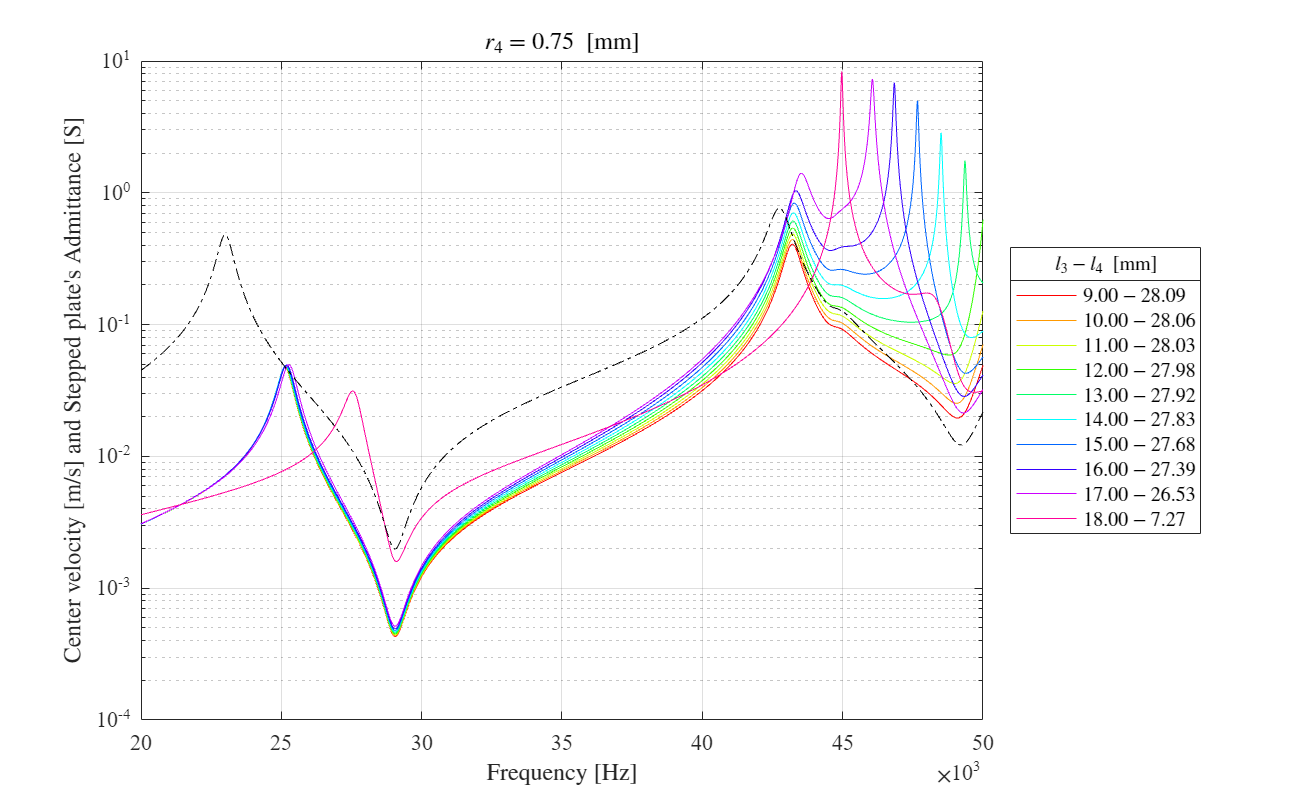

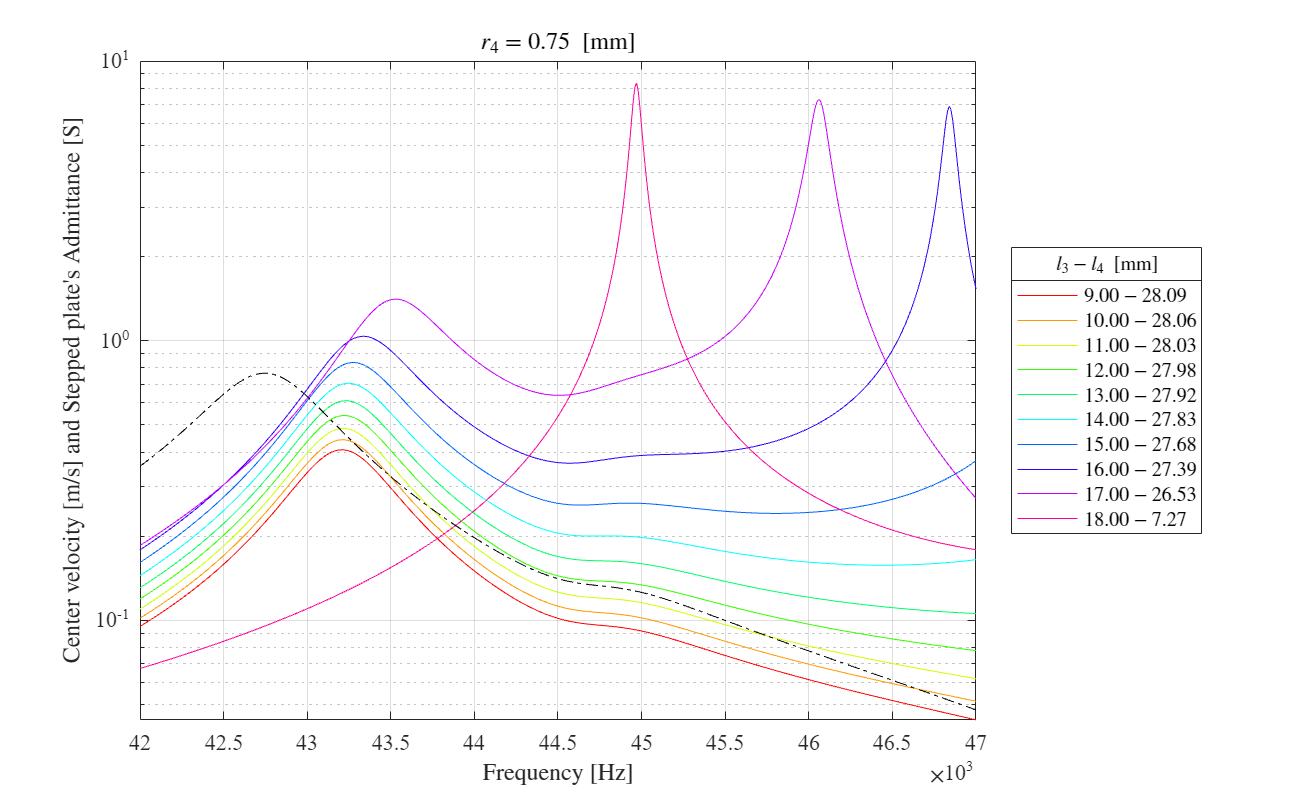

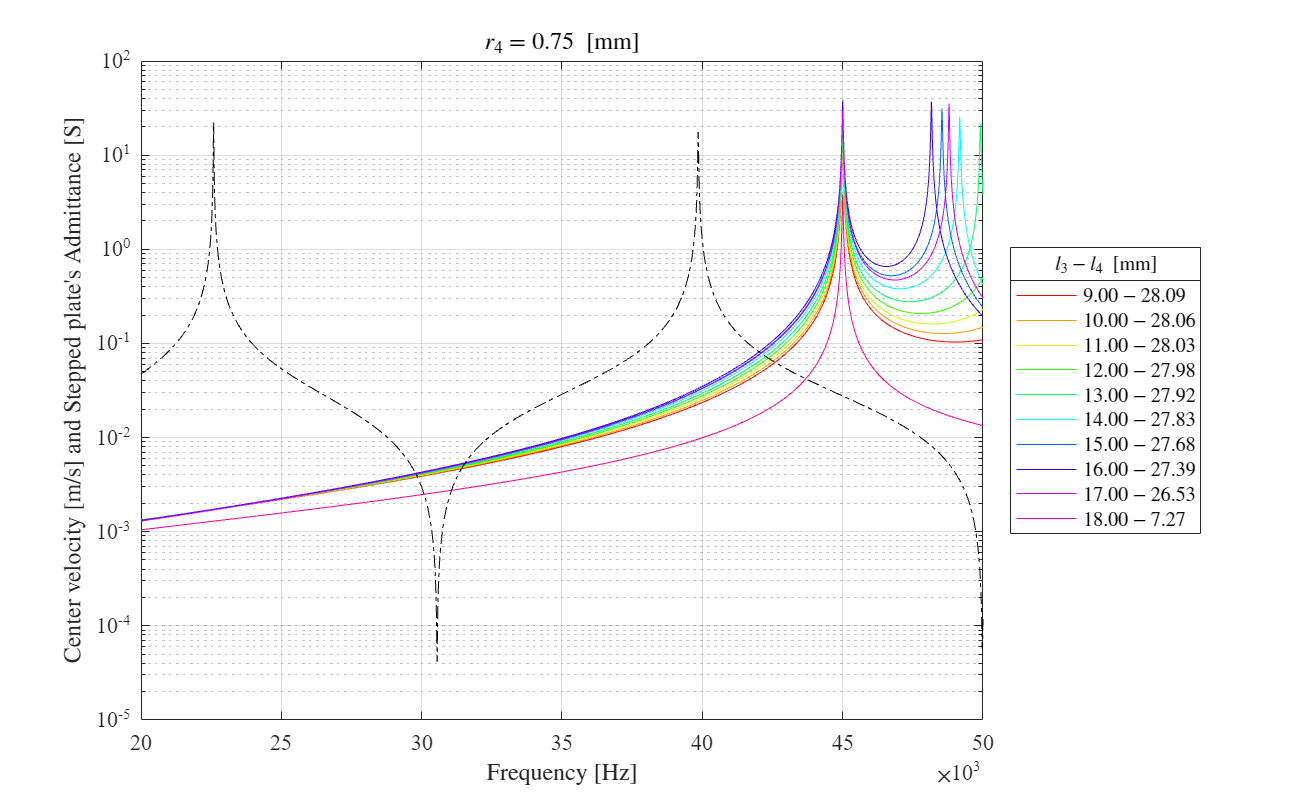

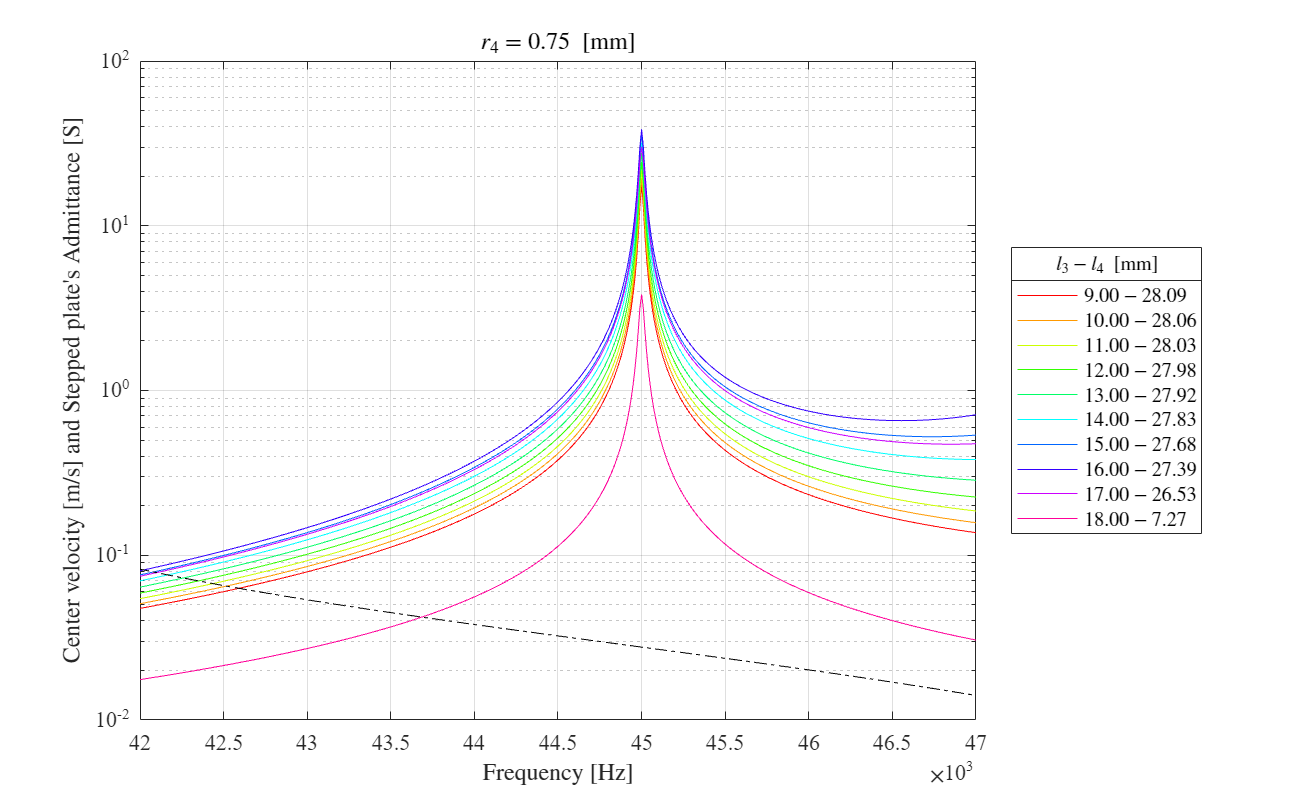

kCount = 10;
for i = 1:r4Count
    for j = 1:l21Count
        k = find(squeeze(param(1,:,7))); % for nonzero element
        k = k(end-kCount+1:end);
        createfigure_fr_rfe(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
        xlim(gca,[20e3 50e3]);
        % saveas(gcf,"230808 - RFE 48 ECM r4 "+num2str(r4(i)*1e3,'%.2f')+".svg",'svg')
        createfigure_fr_rfe(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
        xlim(gca,[42e3 47e3]);
        % saveas(gcf,"230808 - RFE 48 ECM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

        createfigure_fr_rfe(f,abs(squeeze(uGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_wo_steps))
        xlim(gca,[20e3 50e3]);
        % saveas(gcf,"230808 - RFE 48 ECM r4 "+num2str(r4(i)*1e3,'%.2f')+"_woPlate.svg",'svg')
        createfigure_fr_rfe(f,abs(squeeze(uGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_wo_steps))
        xlim(gca,[42e3 47e3]);
        % saveas(gcf,"230808 - RFE 48 ECM r4 "+num2str(r4(i)*1e3,'%.2f')+"_woPlate_enlarged.svg",'svg')
    end
end

## FEM

uCOMSOLr4_050 = import_COMSOL_array('D -230808 - 48 kHz Stepped-plate transducer_r4_0.5.txt');
uCOMSOLr4_050 = uCOMSOLr4_050(:,5:6);   % taking the freq. and vel.
uCOMSOLr4_050 = reshape(uCOMSOLr4_050,length(uCOMSOLr4_050)/kCount,kCount,[]);

Error using reshape
Size arguments must be real integers.

uCOMSOLr4_050 = permute(uCOMSOLr4_050,[2 1 3]);

uCOMSOLr4_075 = import_COMSOL_array('D -230808 - 48 kHz Stepped-plate transducer_r4_0.5.txt');
uCOMSOLr4_075 = uCOMSOLr4_075(:,5:6);   % taking the freq. and vel.
uCOMSOLr4_075 = reshape(uCOMSOLr4_075,length(uCOMSOLr4_075)/kCount,kCount,[]);
uCOMSOLr4_075 = permute(uCOMSOLr4_075,[2 1 3]);

i=1;
k = find(squeeze(param(1,:,7))); % for nonzero element
k = k(end-kCount+1:end);
createfigure_fr_rfe(abs(uCOMSOLr4_050(1,:,1)),abs(uCOMSOLr4_050(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
xlim(gca,[25e3 75e3]);
% saveas(gcf,"230808 - RFE 48 FEM r4 "+num2str(r4(i)*1e3,'%.2f')+".svg",'svg')
createfigure_fr_rfe(abs(uCOMSOLr4_050(1,:,1)),abs(uCOMSOLr4_050(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230808 - RFE 48 FEM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

i=2;
k = find(squeeze(param(1,:,7))); % for nonzero element
k = k(end-kCount+1:end);
createfigure_fr_rfe(abs(uCOMSOLr4_075(1,:,1)),abs(uCOMSOLr4_075(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
xlim(gca,[25e3 75e3]);
% saveas(gcf,"230808 - RFE 48 FEM r4 "+num2str(r4(i)*1e3,'%.2f')+".svg",'svg')
createfigure_fr_rfe(abs(uCOMSOLr4_075(1,:,1)),abs(uCOMSOLr4_075(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230808 - RFE 48 FEM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

## Comp. ECM and FEM

j=1;
i=1;
k = find(squeeze(param(1,:,7))); % for nonzero element
k = k(end-kCount+1:end);
createfigure_fr_rfe_comp(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),abs(uCOMSOLr4_050(1,:,1)),abs(uCOMSOLr4_050(:,:,2)));
xlim(gca,[25e3 75e3]);
% saveas(gcf,"230808 - RFE 48 COM r4 "+num2str(r4(i)*1e3,'%.2f')+".svg",'svg')
createfigure_fr_rfe_comp(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),abs(uCOMSOLr4_050(1,:,1)),abs(uCOMSOLr4_050(:,:,2)));
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230808 - RFE 48 COM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

i=2;
k = find(squeeze(param(1,:,7))); % for nonzero element
k = k(end-kCount+1:end);
createfigure_fr_rfe_comp(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),abs(uCOMSOLr4_075(1,:,1)),abs(uCOMSOLr4_075(:,:,2)));
xlim(gca,[25e3 75e3]);
% saveas(gcf,"230808 - RFE 48 COM r4 "+num2str(r4(i)*1e3,'%.2f')+".svg",'svg')
createfigure_fr_rfe_comp(f,abs(squeeze(uPlateGlobal(i,j,k,:,5))),r4(i),l3(k),squeeze(param(i,k,5)),abs(uCOMSOLr4_075(1,:,1)),abs(uCOMSOLr4_075(:,:,2)));
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230808 - RFE 48 COM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

## Comp. FEMs

i=2;
uCOMSOLr4_075_std = import_COMSOL_array('230829 - Standard model - 48 kHz.txt');
uCOMSOLr4_075_std = uCOMSOLr4_075_std(:,3:4);   % taking the freq. and vel.
uCOMSOLr4_075_std = reshape(uCOMSOLr4_075_std,length(uCOMSOLr4_075_std)/kCount,kCount,[]);
uCOMSOLr4_075_std = permute(uCOMSOLr4_075_std,[2 1 3]);

createfigure_fr_rfe(abs(uCOMSOLr4_075_std(1,:,1)),abs(uCOMSOLr4_075_std(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),f,abs(1./Z_p_w_steps))
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230829 - RFE 48 FEM r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')

createfigure_fr_rfe_comp(abs(uCOMSOLr4_075(1,:,1)),abs(uCOMSOLr4_075(:,:,2)),r4(i),l3(k),squeeze(param(i,k,5)),abs(uCOMSOLr4_075_std(1,:,1)),abs(uCOMSOLr4_075_std(:,:,2)));
xlim(gca,[47e3 52e3]);
% saveas(gcf,"230829 - RFE 48 COM FEMs r4 "+num2str(r4(i)*1e3,'%.2f')+"_enlarged.svg",'svg')